%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT

%Airfoil Parameters
Cla = 6

Cla = 6

Tmax = 0.12

Tmax = 0.1200

LocMaxT = 0.3

LocMaxT = 0.3000

PerLamFlow = 0.1

PerLamFlow = 0.1000


%Planform Parameters
S = 1500; %ft^2
TaperRatio = 0.01:0.01:1;
Sexp = 750; %ft^2
SweepMaxT = 0; %Degrees
SweepQuartC = 0; %Degrees
Q = 1.01 %For HIGH or MID wing

Q = 1.0100

AR = 8

AR = 8


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3; %Slug/ft^3
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Calc Lift Curve Slope
beta = sqrt(1-M^2)

beta = 0.8134

eta = Cla/(2*pi)

eta = 0.9549

CLa = (2*pi*AR*Sexp/S)/(2+sqrt(4+(AR^2*beta^2)/eta^2*(1+(tand(SweepMaxT)^2)/beta^2)))

CLa = 4.9705


K=0

K = 0


%Induced Drag Factor
for x=1:100
    
    Ne = 0; %Num of engines ON TOP of Wing
    TaperFunc = 0.005*(1+1.5*(TaperRatio(x)-0.6)^2)
    K(x) = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/((cosd(SweepQuartC))^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)
end

TaperFunc = 0.0076

K = 0.0488

TaperFunc = 0.0075

K =     0.0488    0.0488


TaperFunc = 0.0074

K =     0.0488    0.0488    0.0487


TaperFunc = 0.0074

K =     0.0488    0.0488    0.0487    0.0487


TaperFunc = 0.0073

K =     0.0488    0.0488    0.0487    0.0487    0.0487


TaperFunc = 0.0072

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486


TaperFunc = 0.0071

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486


TaperFunc = 0.0070

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486


TaperFunc = 0.0070

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486


TaperFunc = 0.0069

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485


TaperFunc = 0.0068

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485


TaperFunc = 0.0067

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485


TaperFunc = 0.0067

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485


TaperFunc = 0.0066

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484


TaperFunc = 0.0065

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484


TaperFunc = 0.0065

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484


TaperFunc = 0.0064

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484


TaperFunc = 0.0063

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483


TaperFunc = 0.0063

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483


TaperFunc = 0.0062

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483


TaperFunc = 0.0061

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483


TaperFunc = 0.0061

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483


TaperFunc = 0.0060

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482


TaperFunc = 0.0060

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482


TaperFunc = 0.0059

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482


TaperFunc = 0.0059

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482


TaperFunc = 0.0058

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482


TaperFunc = 0.0058

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482


TaperFunc = 0.0057

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481


TaperFunc = 0.0057

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0056

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481


TaperFunc = 0.0056

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481


TaperFunc = 0.0055

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481


TaperFunc = 0.0055

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481


TaperFunc = 0.0055

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481


TaperFunc = 0.0054

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480


TaperFunc = 0.0054

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480


TaperFunc = 0.0054

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480


TaperFunc = 0.0053

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480


TaperFunc = 0.0053

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480


TaperFunc = 0.0053

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480


TaperFunc = 0.0052

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480


TaperFunc = 0.0052

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480


TaperFunc = 0.0052

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480


TaperFunc = 0.0052

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480


TaperFunc = 0.0051

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0479


TaperFunc = 0.0051

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0479    0.0479


TaperFunc = 0.0051

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0479    0.0479    0.0479


TaperFunc = 0.0051

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0479    0.0479    0.0479    0.0479


TaperFunc = 0.0051

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0479    0.0479    0.0479    0.0479    0.0479


TaperFunc = 0.0051

K =     0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0480    0.0479    0.0479    0.0479    0.0479    0.0479


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0050

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0051

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0051

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0051

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0051

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0051

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0051

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0052

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0052

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0052

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0052

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0053

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0053

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0053

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0054

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0054

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0054

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0055

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0055

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0055

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0056

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0056

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0057

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0057

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0058

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0058

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0059

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0059

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0060

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0060

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0061

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0061

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


TaperFunc = 0.0062

K = 1×30
    0.0488    0.0488    0.0487    0.0487    0.0487    0.0486    0.0486    0.0486    0.0486    0.0485    0.0485    0.0485    0.0485    0.0484    0.0484    0.0484    0.0484    0.0483    0.0483    0.0483    0.0483    0.0483    0.0482    0.0482    0.0482    0.0482    0.0482    0.0482    0.0481    0.0481


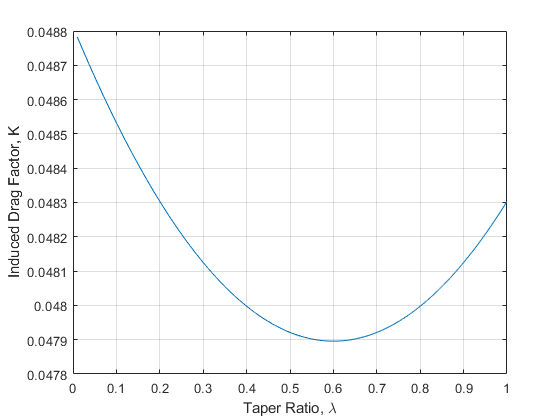


plot (TaperRatio,K)
xlabel('Taper Ratio, \lambda')
ylabel('Induced Drag Factor, K')
grid on